clc;
clear all;
close all;

B = 10*1e9;
%% system parameters
Sysparam = struct();

Sysparam.Nt = 256;
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 300*1e9;%carrier frequency 
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 16; %number of TTDs for each RF chain
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
Sysparam.L = 1 ; % number of paths equals to number of RF chains
%Sysparam.Nrf=Sysparam.L;
% compute discrete time-delay values
Sysparam.Q = 256; % number of fixed TTD element 
%Sysparam.T = Sysparam.tmax*(0:1:Sysparam.Q-1)/(Sysparam.Q-1);
%% Sub-carrier frequencies

%% simulation parameters
Simparam = struct();

%Simparam.phi = [0.62;0.62;0.62;0.62];
%Simparam.phi = 0.2*pi*ones(Sysparam.L,1); %AoD;
%Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
%Simparam.P = -20:5:15;% transmit power in dB
%Simparam.Rho = 10.^(Simparam.P/10); %transmit power
%Simparam.Niter = 50; %channel realizations
Sysparam.f = B;
%Simparam.phi = pi*rand(Sysparam.L,1)-0.5*pi %AoD;
Simparam.phi = 0.35*pi*ones(Sysparam.L,1)%AoD;

Simparam = struct with fields:
    phi: 1.0996


%Simparam.phi = pi*((0.5-1/3)*rand(Sysparam.L,1)+1/3) %AoD;
SpatialDirection = sin(Simparam.phi)

SpatialDirection = 0.8910


for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 

Mrange = 1:1:1000;
for i = 1:length(Mrange)
    for k = 1:Sysparam.K
        g(i,k) = abs(sin(Mrange(i)*pi*(Sysparam.xi(k)-1)*sin(Simparam.phi)/2)/(Mrange(i)*sin(pi*(Sysparam.xi(k)-1)*sin(Simparam.phi)/2))); 
    end 
end 

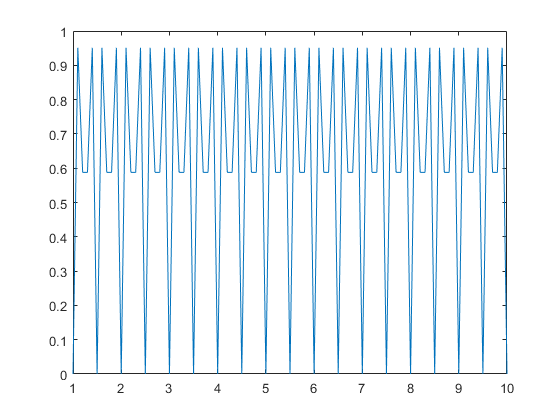

xSet = 1:0.1:10;
for i = 1:length(xSet)
   for k = 1:Sysparam.K
    g2(i,k) = abs(sin(Sysparam.Nt*pi*xSet(i)));
   end 
end
plot(xSet,g2(:,1))